# **Solar Cooker Model**

**Jacob Smilg & Daniel Park**

## **Question:**

### **Design - What is the ideal pot material and smallest mirror diameter for a parabolic solar cooker to raise the temperature of two liters of water from 20°C to 100°C in 5 minutes?**

This is a design question because we are trying to find particular parameters of a solar cooker that accomplish a specific goal. Asking this question could be useful to finding an optimal solar cooker design for people who live in areas such as the Himalayas where there is limited access to traditional fuels. We believe this question is interesting because it has the potential to result in a design that isn't feasible to construct or use.

## **Methodology/Model:**

To answer our question, we will create a script that will model our parabolic solar cooker onto a graph that shows the time it takes to boil two liters of water for each diameter of the mirror. This graph will help us determine at what diameter the mirror should be in order for each pot type for the water to reach its boiling point in five minutes. 

### **Schematic & Photo:**

To first visualize what kind of parabolic solar cooker we are working with, we placed images of the schematic and real photograph of the cooker. These two photos below represent what our theoretical solar cooker model could look like:

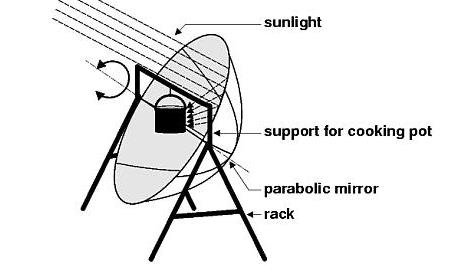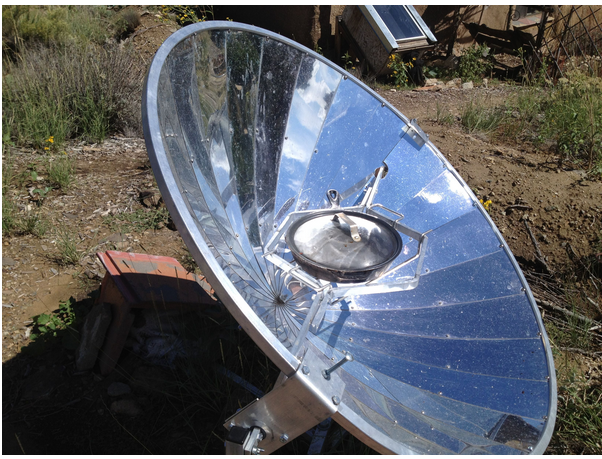

Before we get into modeling, we need to construct a stock and flow model based on the three mechanisms of energy transfer (radiation, conduction, and convection) in order to determine the material of the pot and the diameter of the parabolic mirror for a solar cooker that would accomplish the goal laid out in the question. The stock and flow model will help us visualize what our processes are and help us solve how we want to mathematically represent these energy transfers into a script. 

### **Stock and Flow Diagram:**

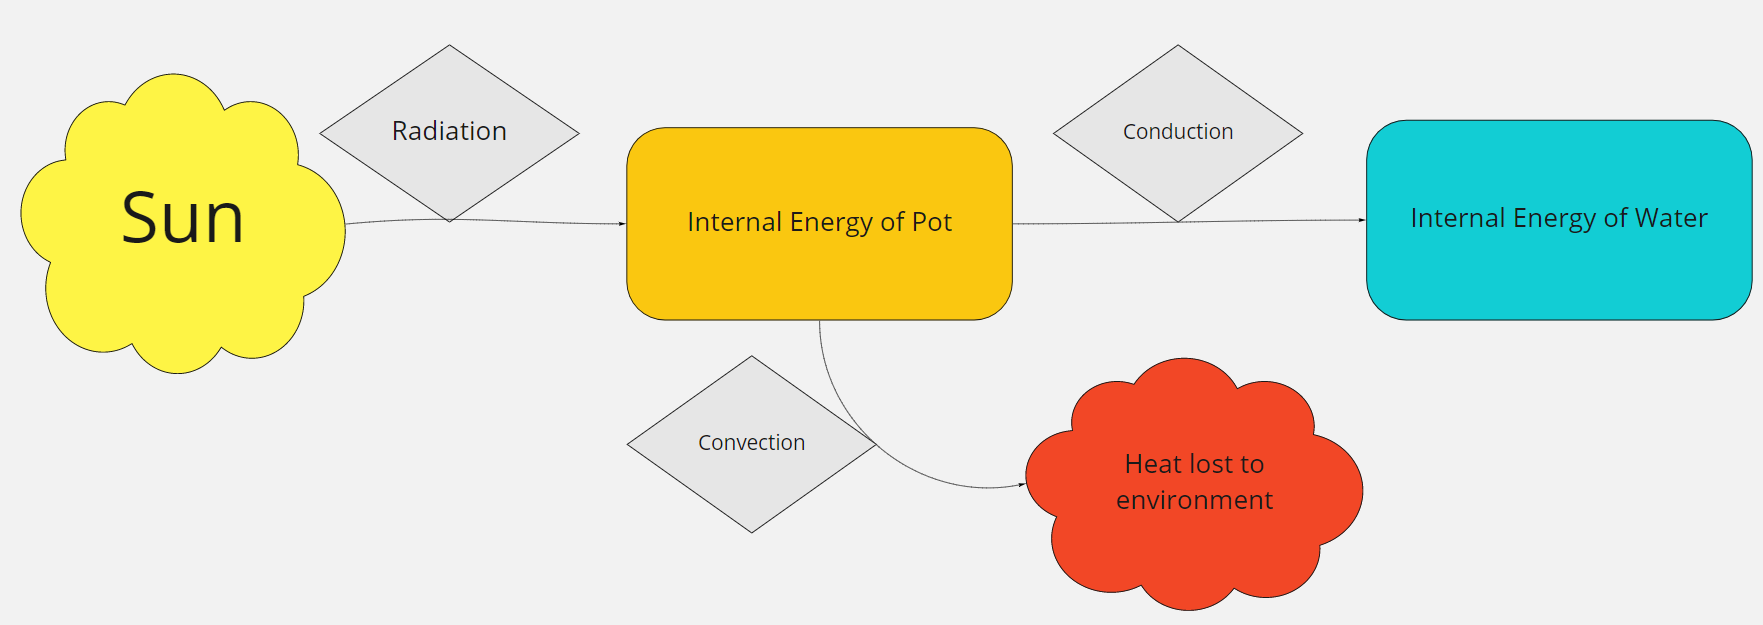

**Stocks:**

- Sun (Source)

- Internal Energy of the Cooker

- Internal Energy of the Water

**Flows:**

- Radiation (Sun → Mirrors/Pot)

- Conduction (Pot → Water)

- Convection (Cooker → Air)

**Equations and Associated Variables:**

- $\frac{\mathrm{dQ}}{\;\mathrm{dt}}=\mathrm{elA}$ ***(flow of radiation from sun to the mirrors/pot)***

- $\mathrm{e}$: emissivity of the pot - this be between 0 and 1, and represents how efficient the pot's absorption of radiation is.

- $\mathrm{I}$: insolation (W/m^2) is the amount of energy the sun is "transmitting".

- $\mathrm{A}:$ projected surface area (m^2) - the area of a circle of the diameter to the mirrors is used.

- $\frac{\textrm{dQ}}{\textrm{dt}}=\frac{\textrm{kA}}{d\Delta T}$ ***(flow of conduction from pot to the water)***

- $\mathrm{k}$: thermal conductivity of the pot material (W/m K)

- $\mathrm{A}$: surface area of the parts of the pot touching the water (m^2)

- $d$: thickness of the pot (m)

- $\Delta T$: difference of the pot temperature and the water temperature

- $\frac{\mathrm{dQ}}{\mathrm{dt}}=\mathrm{hA}\left(T_{\mathrm{air}} -T_{\mathrm{pot}} \right)$ ***(flow of convection from pot to the air)***

- $\mathrm{h}$: convection coefficient (W/m^2 K)

- $\mathrm{A}$: surface area of the pot and lid

- $T_{\textrm{air}} \;\&\;T_{\textrm{pot}}$: Temperature of the air and the pot (K)

#### **Development and Refinement**

Our first iteration of our model was a simple model that only had single parameters for the material of the pot and the diameter of parabolic mirrors rather than sweeping them like we do later in the report. We also only had two stocks (sun and the water) and one flow to represent the water boiling from the sun's rays. 

Additionally, we specified a time that our model would end (30 minutes) compared to our final model where we used the event parameter of "odeset" to end our model when the graph reaches the boiling point. 

**Assumptions and Abstractions:**

- The mirrors will transfer all of the radiation energy from the sun to the cooker without any loss. If this were simulated, the effect would be minimal, adding needless complexity.

- We are assuming the dimensions of the pot to hold about 2L of water. (14 cm diameter x 14 cm depth x 0.5 cm thickness).

- We are assuming the pot has a lid; boiling water without a lid increases heat loss through evaporation and convection between the surrounding air and the water.

**Parameters:**

- Location: The Himalayas (28°N, ~6200m above sea level) 

- Due to the elevation of the Himalayas, the boiling point of water was lower at 352.85 K as opposed to 373.15 K.

- Time and Date: Solar noon on January 1 (insolation = 921 W/m^2)

- Wind speeds: high (convection coefficient = 25).

- These parameters were chosen to provide difficult, but realistic conditions for our solar cooker to operate.

- We also included three different materials (Copper, Aluminum, 304 Stainless Steel) for the cooking pot, and ran simulations on all three of them.

- The absorption efficiency was set to 0.75 because we were assuming that the outside coating of the pots were dark colored.

**Verification:**

- Our model was verified by examining a single mirror diameter, and making sure that the behaviors of the temperatures made sense. This lets us know that our graph that gives the final results, which doesn't show the rise in temperature, is based on reasonable foundations.

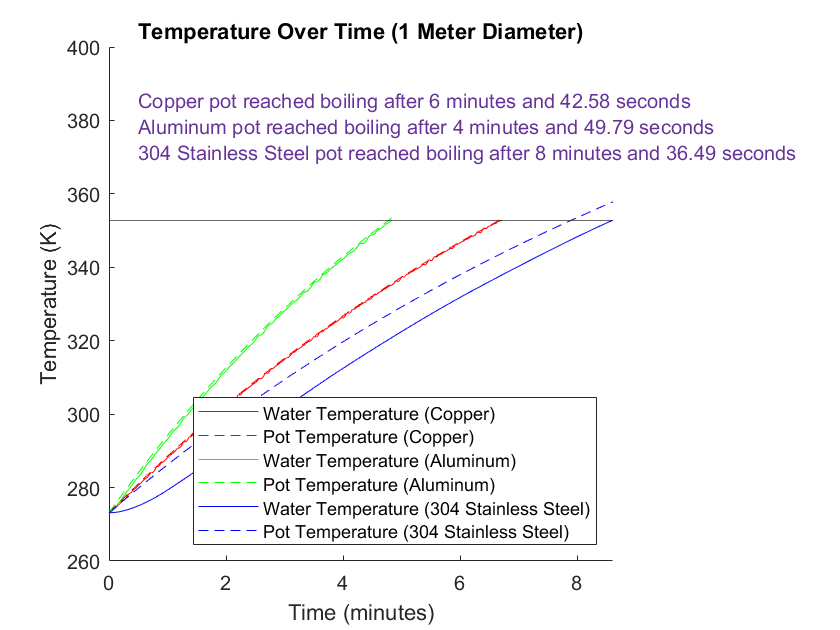

materials = ["Copper", "Aluminum", "304 Stainless Steel"];
figure(); 
hold on

xlabel('Time (minutes)');
ylabel('Temperature (K)');
title(sprintf('Temperature Over Time (1 Meter Diameter)'))
colors = {'r','r','g','g','b','b'};
colororder(colors);

a = gca;
a.Position(3) = 0.6;
boilTime = "";

for i = 1:length(materials)
    [T, waterTemp, potTemp, endTime] = single_diameter_v2(materials(i), 1);
    [endMinute, endSecond] = minutesToMinutesSeconds(endTime);
    plot(T, waterTemp, '-', T, potTemp,'--');
    xlim([0 endTime])
    ylim([260 400])
    
    boilTime = boilTime + sprintf("%s pot reached boiling after %i minutes and %.2f seconds \n",...
        materials(i), endMinute, endSecond);
end

text(0.5,375,boilTime,'Color','#663399')

yline(352.85); % Boiling temperature in K at 6172 m elevation
legend('Water Temperature (Copper)','Pot Temperature (Copper)',...
    'Water Temperature (Aluminum)','Pot Temperature (Aluminum)',...
    'Water Temperature (304 Stainless Steel)','Pot Temperature (304 Stainless Steel)',...
    'Location', 'Southeast');

**Validation:**

If we were to validate our model, we would most likely get real data from a solar cooker similar in structure and functionality to the one shown in the "Schematic & Photo" section of the report. If possible, we would need to get boiling data from the solar cooker that the previous Olin student built in the Himalayas for the most accurate data based on our current parameters. However, we could also get our own water boiling data by constructing a parabolic solar cooker of our own, make sure both of our constraints and parameters are similar in our script and in the real life model, and compare them together. 

## **Results:**

**Diameter Sweep:**

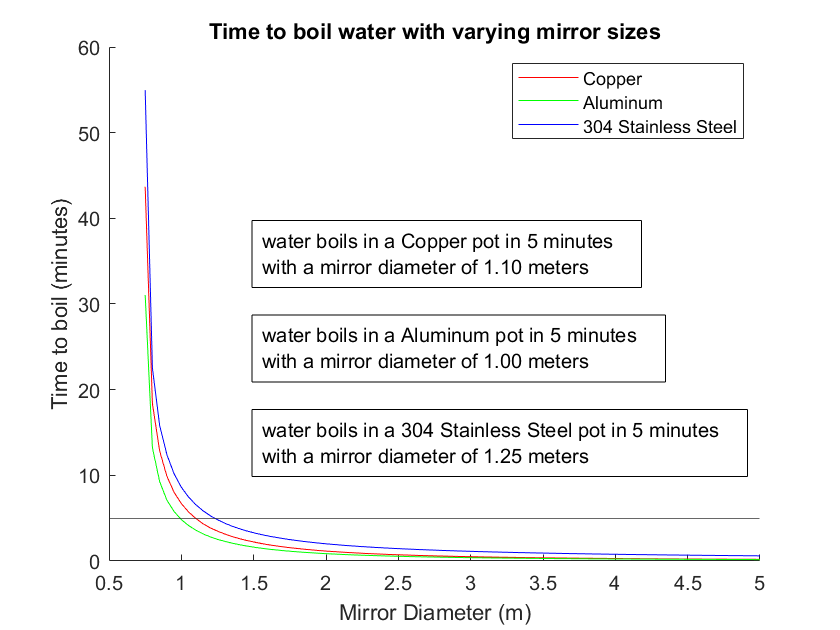

materials = ["Copper", "Aluminum", "304 Stainless Steel"];
figure();
hold on

xlabel('Mirror Diameter (m)');
ylabel('Time to boil (minutes)');
title(sprintf("Time to boil water with varying mirror sizes"))
colors = {'r','g','b'};
colororder(colors);

diameterRange = .5:.05:5;
endTimes = zeros(length(diameterRange), 1);

dimensionIteration = 0;

for i = 1:length(materials)
    [time,waterTemp,potTemp,endTime] = single_diameter_v2(materials(i), 1);
    for diameterIndex = 1:length(diameterRange)
        [~,~,~,endTime] = single_diameter_v2(materials(i), diameterRange(diameterIndex));
        if endTime
            endTimes(diameterIndex) = endTime;
        else
            endTimes(diameterIndex) = NaN;
        end
    end
    
    plot(diameterRange, endTimes)
    [val, idx] = min(abs(endTimes-5));
    threshold = diameterRange(idx);
    
    dim = [.3 .55-dimensionIteration .1 .1];
    
    dimensionIteration = dimensionIteration + 0.15;
    
    txt = sprintf("water boils in a %s pot in 5 minutes \nwith a mirror diameter of %.2f meters", materials(i), threshold);
    annotation('textbox', dim ,'String', txt)
end
yline(5);
legend('Copper','Aluminum','304 Stainless Steel')

## **Interpretation:**

Our results give us the minimum mirror diameter for each pot material to boil water in 5 minutes. From there, you can see that the material with the smallest mirror diameter is the best. With our parameters, we see that an aluminum pot can boil water in 5 minutes with a 1 meter mirror — a direct answer to our question.

This answer is good, but probably only in the specific location we chose. The boiling point of water changes significantly depending on the elevation, which in turn causes different times to reach boiling. However, this isn't a limitation of the model itself, as these parameters can be changed easily.

But if we had to draw limitations and continue iterating our model, we would most likely try to accurately depict other independent variables that may affect cooking times. For example, we would model our cooker operating during different times of the year rather than a single point in the year (for us it was January 1 at solar noon) and also possibly take in account of different latitudes for different locations instead of only taking in account that the cooker will be used in the Himalayas. Athough these are suggestions rather than definites, we believe that making our model account for more parameters beyond the current ones we are sweeping would make our information about specific boiling times and diameters more accurate.

## **Works Cited:**

Miro Board Link: [https://miro.com/app/board/o9J_kg0-7nE=/](https://miro.com/app/board/o9J_kg0-7nE=/)

Copper and Aluminum Properties: [https://www.periodic-table.org](https://www.periodic-table.org)

304 Stainless Steel properties: [https://www.aksteel.com/sites/default/files/2018-01/304304L201706_1.pdf](https://www.aksteel.com/sites/default/files/2018-01/304304L201706_1.pdf)

Intro to Thermal Packet: [https://olin.instructure.com/courses/138/files/10240/](https://olin.instructure.com/courses/138/files/10240/)

Solar Insulation Calculator: [https://www.pveducation.org/pvcdrom/properties-of-sunlight/calculation-of-solar-insolation](https://www.pveducation.org/pvcdrom/properties-of-sunlight/calculation-of-solar-insolation)

Mount Everest Temperature Data: [https://www.meteoblue.com/en/weather/historyclimate/weatherarchive/mount-everest_nepal_1283416](https://www.meteoblue.com/en/weather/historyclimate/weatherarchive/mount-everest_nepal_1283416)

Water Boiling Point vs. Altitude: [https://www.engineeringtoolbox.com/boiling-points-water-altitude-d_1344.html](https://www.engineeringtoolbox.com/boiling-points-water-altitude-d_1344.html)